# PCB Anomaly Detection Using FCDD

In this live script, you will see how to build another type of anomaly detector- an FCDD anomaly detector- using the same printed circuit board dataset. FCDD is a more computationally efficient algorithm than PatchCore, so you can train your own detector in 20 minutes! 

The general workflow stays the same, but there are a few differences in setting up the detector, splitting the data, and training the detector. As you work through this reading, think about the similarities and differences between the PatchCore and FCDD detectors.

You'll also notice that while the training and usage speed has increased a lot, the accuracy is notably lower. This is a trade-off you need to consider when developing your own anomaly detector.

## Choose an Anomaly Detection Algorithm

First, we set up the baseline FCDD anomaly detector model in a similar way to the PatchCore model. The main difference is that PatchCore uses ResNet-18. For FCDD, you specify a backbone. We choose the ResNet-18 backbone here so you can compare the two approaches more directly.

When creating the backbone network, we also need to specify the "depth" of the network, which represents the number of downsampling operations in the network. Any value between 2 and 4 would be a good place to start here, so we set a depth of 3. 

% Set up the backbone network
backboneNetwork = pretrainedEncoderNetwork("resnet18",3);
detector = fcddAnomalyDetector(backboneNetwork);

## Import and Split the Data

Next, import the printed circuit board images and split them into train, calibration, and test sets. Notice that for the FCDD algorithm, you need some anomalous images to train the model, whereas PatchCore only used normal images to train the model. As a result, you also need to further split the training data into normal and anomaly images, since they are passed in separately during training.

% Read in the printed circuit board images located in
% <your course file location>...\Data\Printed Circuit Board
filename = "E:\Semester Pendek\MATLAB\Deep Learning for Computer Vision\Data\Printed Circuit Board";
imds = imageDatastore(filename,"IncludeSubfolders",true,"LabelSource","foldernames");

% Split data into train/calibration/test
[imdsTrain,imdsCal,imdsTest] = splitAnomalyData(imds,"Anomaly", ...
    NormalLabelsRatio=[0.5,0.1,0.4], ...
    AnomalyLabelsRatio=[0.05,0.2,0.75]);

Splitting anomaly dataset
-------------------------
* Finalizing... Done.
* Number of files and proportions per class in all the datasets:

                      Input                    Train                Validation                Test        
               ____________________    _____________________    ___________________    ___________________

               NumFiles     Ratio      NumFiles      Ratio      NumFiles     Ratio     NumFiles     Ratio 
               ________    ________    ________    _________    ________    _______    ________    _______
                       


% Split training data into normal and anomaly
[imdsTrainNormal,imdsTrainAnomaly] = splitAnomalyData(imdsTrain,"Anomaly", ...
    NormalLabelsRatio=[1 0 0],AnomalyLabelsRatio=[0 1 0],Verbose=false);

## Train the Detector

Now that your data is prepared, set up the training options and train the FCDD detector using both the normal training images and anomaly training images. We use 10 epochs here because this took around 40 minutes to train on our CPU. If you have more time or a GPU available, try increasing the number of epochs to 15 or 20 to see the model improves further.

% Set up the training options
options = trainingOptions("adam", ...
    Plots="training-progress", ...
    MaxEpochs=10, ...
    BatchNormalizationStatistics="moving");

% Train detector
detector = trainFCDDAnomalyDetector(imdsTrainNormal,imdsTrainAnomaly,detector,options)

Computing Input Normalization Statistics.
 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingFcddLoss
    _____    _________    ___________    _________    ________________


## Predict Anomaly Scores of Calibration Set

Using the trained model, you can again predict anomaly scores for each calibration image and use this result to calculate and set the anomaly threshold. This step, and all subsequent steps, are entirely the same as the ones you saw for PatchCore. The code doesn't take long to run, so compare your results here to the results from earlier!

% Predict the anomaly scores of images in the calibration set
scores = predict(detector,imdsCal);

## Visualize Anomaly Scores in a Histogram

Plot these results in a histogram to see the distribution of anomaly scores for normal and anomalous images.

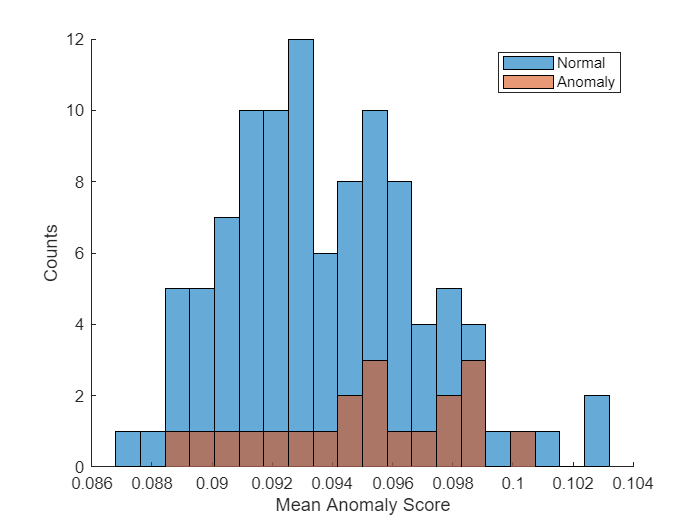

% Get the anomalous image indices
labels = imdsCal.Labels~="Normal";
numBins = 20;

% Save the edge values 
[~,edges] = histcounts(scores,numBins);
figure
hold on

% Plot the histograms with the edge values
hNormal = histogram(scores(labels==0),edges);
hAnomaly = histogram(scores(labels==1),edges);
hold off

% Add the legend and axis labels
legend([hNormal,hAnomaly],"Normal","Anomaly")
xlabel("Mean Anomaly Score")
ylabel("Counts")

## Set the Anomaly Threshold

% Select an anomaly threshold 
thresh = anomalyThreshold(labels,scores,true)

thresh = single
0.0945


% Set the anomaly threshold for the detector
detector.Threshold = thresh;

## Evaluate the Model

Now, classify the test images as normal/anomaly and evaluate the results. 

% Classify the test images
testSetPredLabels = classify(detector,imdsTest);

% Calculate test set accuracy metrics
testSetTrueLabels = imdsTest.Labels;
metrics = evaluateAnomalyDetection(testSetPredLabels,testSetTrueLabels,"Anomaly");

% Display the confusion matrix results
M = metrics.ConfusionMatrix{:,:};
confusionchart(M,["Normal","Anomaly"])

## Visualize the Anomaly Maps

You could also visualize the anomaly maps again to see how the model makes its predictions.

% Find the minimum and maximum anomaly scores in all calibration images
minMapCal = inf;
maxMapCal = -inf;
reset(imdsCal)
while hasdata(imdsCal)
    img = read(imdsCal);
    map = anomalyMap(detector,img);
    minMapCal = min(min(map,[],"all"),minMapCal);
    maxMapCal = max(max(map,[],"all"),maxMapCal);
end
% Save these values as the display range
displayRange = [minMapCal,maxMapCal];

% Save the subset of images you want to view anomaly maps for
% Here we focus on the correctly identified anomaly images
testSetAnomalyLabels = testSetTrueLabels' == "Anomaly";
idxTruePositive = find(testSetAnomalyLabels & testSetPredLabels);
dsExample = subset(imdsTest,idxTruePositive);

% Select an image from the subset
img = readimage(dsExample,1);

% Calculate the pixel-level anomaly scores
map = anomalyMap(detector,img);

% Visualize the anomaly scores using the display range from earlier
montage({img,anomalyMapOverlay(img,map,"MapRange",displayRange,"Blend","equal")})

*Copyright 2024 The MathWorks, Inc.*